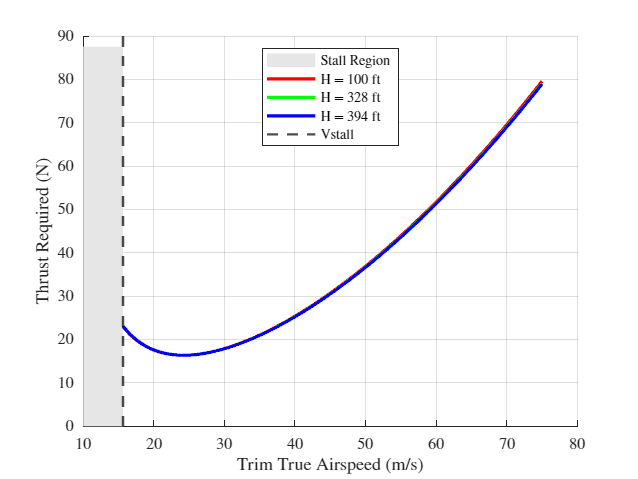

clc
clear

%% Physical Constants
g = 9.81;               % Acceleration due to gravity [m/s^2]
T_Amax = 45;            % Maximum available thrust [N]
mass = 25;              % Aircraft mass [kg]
W2 = mass*g;            % Weight [N]
WS = 17.961*g;          % Wing loading [N/m^2]
rho1 = 1.225;           % Air density at sea level [kg/m^3]
CL_max = 1.2;           % Maximum lift coefficient
K = 0.0689;             % Lift-induced drag coefficient
CD0 = 0.0168;           % Zero-lift drag coefficient
S = 1.364;              % Wing area [m^2]
H_def = 328.084;        % Default cruise altitude [ft]
W_def = 24.5 * g;       % Default weight [N]
c_tp = 6.472e-5;        % Thrust-specific fuel consumption [kg/Ns]

%% Velocity range
V_trim = linspace(10,75,1000); % Velocity range for analysis [m/s]

%% Altitude effects
H = [100, 328, 393.701]; % Altitudes to analyze [ft]
CL_trim = zeros(length(H), length(V_trim));  
TR_H = zeros(length(H), length(V_trim));    
SAR_H = zeros(length(H), length(V_trim));   

for n = 1:length(H)
    [~, ~, rho, ~] = get_atmosprop(H(n) * 0.3048); 
    CL = W_def ./ (0.5 * rho .* V_trim.^2 * S);  
    CD = CD0 + K .* CL.^2;                      
    CL_trim(n, :) = CL;
    TR_H(n, :) = 0.5 * rho .* V_trim.^2 * S .* CD;
    SAR_H(n, :) = V_trim ./ (TR_H(n, :) .* c_tp); 
end

%% Weight effects
W = [25, 23.5, 22] .* g; % Weights to analyze [N]
TR_W = zeros(length(W), length(V_trim));
SAR_W = zeros(length(W), length(V_trim));
SE_W = zeros(length(W), length(V_trim));

for n = 1:length(W)
    [~, ~, rho, ~] = get_atmosprop(H_def * 0.3048);
    CL = W(n) ./ (0.5 * rho .* V_trim.^2 * S);
    CD = CD0 + K .* CL.^2;
    TR_W(n, :) = 0.5 * rho .* V_trim.^2 * S .* CD;
    SAR_W(n, :) = V_trim ./ (TR_W(n, :) .* c_tp);
    SE_W(n, :) = (1 ./ (TR_W(n, :) .* c_tp)) ./ 60;
end

%% Performance calculations
Vmax = calc_Vmax(T_Amax, W2, CD0, K, rho1, S);
Vstall = sqrt((2 * mass * g)/(rho1 * S * CL_max)); % Stall speed [m/s]
idx_vstall = find(V_trim >= Vstall, 1);

%% Plot 1: Thrust Required vs Velocity (Altitude Variation)
figure
hold on
x_fill = [min(V_trim) Vstall Vstall min(V_trim)];
y_fill = [0 0 max(TR_H(:))*1.1 max(TR_H(:))*1.1];
fill(x_fill, y_fill, [0.9 0.9 0.9], 'EdgeColor', 'none');
xline(Vstall, '--k', 'LineWidth', 1.5);

plot(V_trim(idx_vstall:end), TR_H(1, idx_vstall:end), 'r-', 'LineWidth', 2) % Red
plot(V_trim(idx_vstall:end), TR_H(2, idx_vstall:end), 'g-', 'LineWidth', 2) % Green
plot(V_trim(idx_vstall:end), TR_H(3, idx_vstall:end), 'b-', 'LineWidth', 2) % Blue

xlabel('Trim True Airspeed (m/s)');
ylabel('Thrust Required (N)');
legend({'Stall Region', 'Vstall', 'H = 100 ft', 'H = 328 ft', 'H = 394 ft'}, 'Location', 'north');
grid on

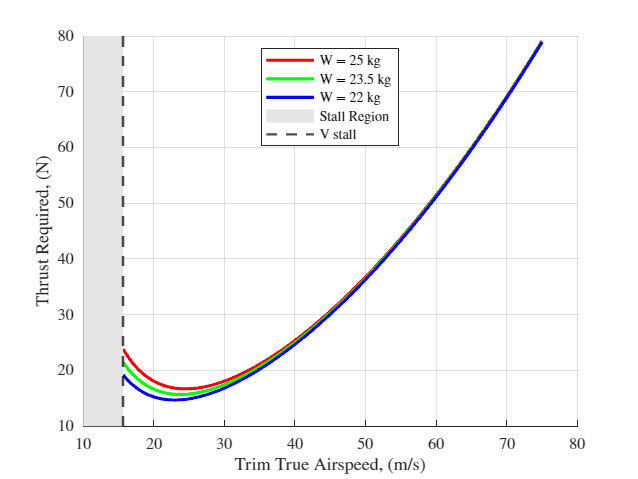


%% Plot 2: Thrust Required vs Velocity (Weight Variation)
figure
hold on
colors = {'r', 'g', 'b'}; % Red, Green, Blue
for n = 1:length(W)
    plot(V_trim(idx_vstall:end), TR_W(n, idx_vstall:end), 'Color', colors{n}, 'LineWidth', 2)
end

yl = ylim;
fill([min(V_trim) Vstall Vstall min(V_trim)], [yl(1) yl(1) yl(2) yl(2)], ...
     [0.9 0.9 0.9], 'EdgeColor', 'none');
xline(Vstall, '--k', 'LineWidth', 1.5);

xlabel('Trim True Airspeed, (m/s)');
ylabel('Thrust Required, (N)');
legend({'W = 25 kg', 'W = 23.5 kg', 'W = 22 kg', 'Stall Region', 'V stall'}, 'Location', 'north');
grid on

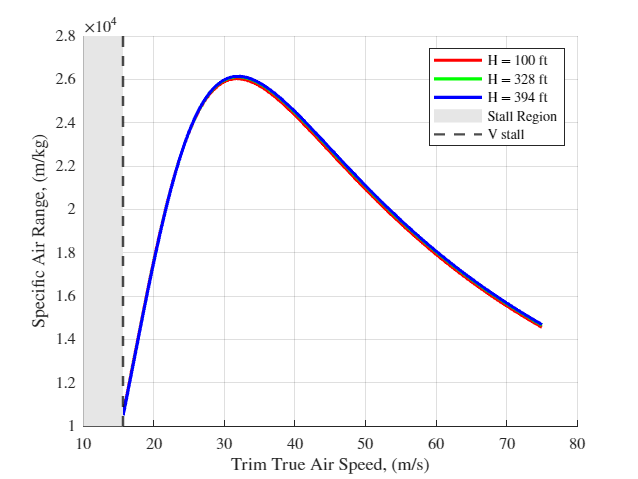


%% Plot 3: SAR vs Velocity (Altitude Variation)
figure
hold on
for n = 1:length(H)
    plot(V_trim(idx_vstall:end), SAR_H(n, idx_vstall:end), 'Color', colors{n}, 'LineWidth', 2)
end

yl = ylim;
fill([min(V_trim) Vstall Vstall min(V_trim)], [yl(1) yl(1) yl(2) yl(2)], ...
     [0.9 0.9 0.9], 'EdgeColor', 'none');
xline(Vstall, '--k', 'LineWidth', 1.5);

xlabel('Trim True Air Speed, (m/s)');
ylabel('Specific Air Range, (m/kg)');
legend({'H = 100 ft', 'H = 328 ft', 'H = 394 ft', 'Stall Region', 'V stall'}, 'Location', 'northeast');
grid on

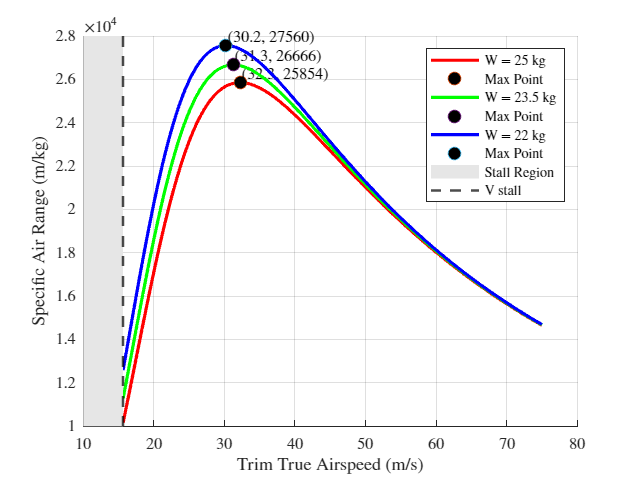


%% Plot 4: SAR vs Velocity (Weight Variation) with Max Points
figure;
hold on;
set(groot, 'defaultAxesTickLabelInterpreter', 'latex');

max_points = zeros(length(W), 2);
for n = 1:length(W)
    x_data = V_trim(idx_vstall:end);
    y_data = SAR_W(n, idx_vstall:end);
    plot(x_data, y_data, 'Color', colors{n}, 'LineWidth', 2);
    
    [max_y, idx] = max(y_data);
    max_x = x_data(idx);
    max_points(n,:) = [max_x, max_y];
    plot(max_x, max_y, 'o', 'MarkerSize', 8, 'MarkerFaceColor', 'k');
    text(max_x, max_y, sprintf('(%.1f, %.0f)', max_x, max_y), ...
        'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');
end

yl = ylim;
fill([min(V_trim) Vstall Vstall min(V_trim)], [yl(1) yl(1) yl(2) yl(2)], ...
     [0.9 0.9 0.9], 'EdgeColor', 'none');
xline(Vstall, '--k', 'LineWidth', 1.5);

xlabel('Trim True Airspeed (m/s)');
ylabel('Specific Air Range (m/kg)');
legend({'W = 25 kg', 'Max Point', 'W = 23.5 kg', 'Max Point', 'W = 22 kg', 'Max Point', 'Stall Region', 'V stall'}, ...
       'Location', 'northeast');
grid on;

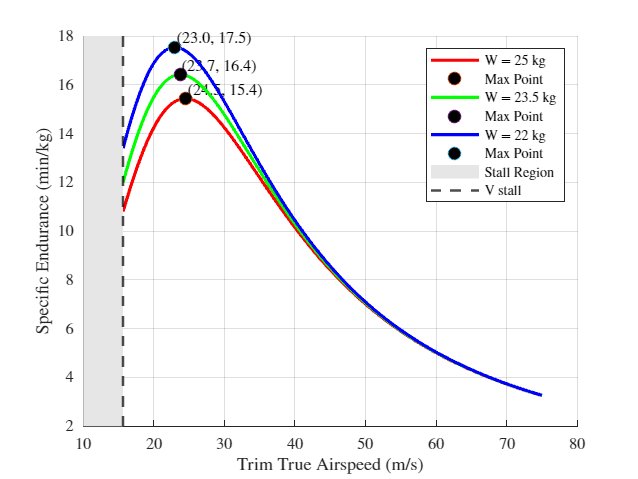


%% Plot 5: SE vs Velocity (Weight Variation) with Max Points
figure;
hold on;
set(groot, 'defaultAxesTickLabelInterpreter', 'latex');

max_points_SE = zeros(length(W), 2);
for n = 1:length(W)
    x_data = V_trim(idx_vstall:end);
    y_data = SE_W(n, idx_vstall:end);
    plot(x_data, y_data, 'Color', colors{n}, 'LineWidth', 2);
    
    [max_y, idx] = max(y_data);
    max_x = x_data(idx);
    max_points_SE(n,:) = [max_x, max_y];
    plot(max_x, max_y, 'o', 'MarkerSize', 8, 'MarkerFaceColor', 'k');
    text(max_x, max_y, sprintf('(%.1f, %.1f)', max_x, max_y), ...
        'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');
end

yl = ylim;
fill([min(V_trim) Vstall Vstall min(V_trim)], [yl(1) yl(1) yl(2) yl(2)], ...
     [0.9 0.9 0.9], 'EdgeColor', 'none');
xline(Vstall, '--k', 'LineWidth', 1.5);

xlabel('Trim True Airspeed (m/s)');
ylabel('Specific Endurance (min/kg)');
legend({'W = 25 kg', 'Max Point', 'W = 23.5 kg', 'Max Point', 'W = 22 kg', 'Max Point', 'Stall Region', 'V stall'}, ...
       'Location', 'northeast');
grid on;